# Warsztaty z Matlab Optimization Toolbox

Dokument został przygotowany jako Live Script aby było łatwiej się z niego uczyć. Jest podzielony na sekcje, które można uruchamiać osobno. Najlepiej go uruchamiac dla uproszczonego widoku wybierając zakładkę Home a potem Layout ->  Command Window Only. W projekcie należy skorzystać z GUI (`optimtool` w Matlabie do wersji 2020b włącznie) lub zwykłych skryptów w nowszych wersjach. Studenci PW mają dostęp do licencji Matlaba po zarejestrowaniu na stronie MathWorks.com. 

#### Prosta optymalizacji funkcji kwadratowej bez ograniczeń za pomocą Matlab Optimization Toolbox

 Ustawiam losowy punkt początkowy z rozkładu normalnego o odchyleniu standardowym 5 i wartości średniej 0.

x0=5*randn(2,1);

Uruchamiam optymalizator przekazując minimalny zestaw argumentów: funkcję celu (zdefiniowanej na końcu tego pliku) oraz punkt początkowy. Znak `@` oznacza uchwyt do funkcji.

x = fminunc(@fun,x0);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


Po zakończeniu pracy optymalizator wypisuje na ekranie informacje o znalezeniu lokalnego minimum oraz powód zatrzymania. Wynik optymalizacji warto wypisać na ekran (lub zapisać do pliku).

fprintf('x = (%.10f, %.10f)\n',x(1),x(2))

0.00000001018052114832
0.00000002144660804504


#### Optymalizacja ze zmianą parametrów

W projekcie należy dostować różne parametry optymalizatora. W tym celu tworzymy zmienną options, które przechowuje obiekt klasy `optimoptions`. Jako pierwszy argument konstruktora podajemy nazwę optymalizatora. Pole `MaxIter` ustawiamy np. na 8.Powoduje to ograniczenie maksymalnej liczby iteracji do 8.

options = optimoptions(@fminunc, 'MaxIter',8);

UWAGA! Składnia zależeć będzie od wybranego solvera. Na wykładzie stosowałem klasę `optimset` do zdefiniowania parametrów algorytmu Neldera-Meada. Natomiast w przypadku algorytmów gradientowych należy zastosować klasę `optimoptions`. Aby uniknąć kłopotów należy dokładnie czytać dokumentację.

Uruchamiamy optymalizator, a wynik zapisujemy do zmiennej `x`. Zapoznajemy się z komunikatem końcowym

x = fminunc(@fun,x0, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


Wypisujemy wynik na ekran

fprintf('x = (%.10f, %.10f)\n',x(1),x(2))

x = (0.0000000102, 0.0000000214)


#### Optymalizacja z rysowaniem wykresów

Każdy z optymalizatorów zaimplementowanych w MATLABie ma zdefiniowane jakieś funkcje rysujące. Możemy z nich skorzystać. Niestety nie wszystkie wykresy wymagane w zadaniu projektowym mogą być narysowane z wykorzystaniem tych predefiniowanych funkcji. Na szczęście, mamy dwie możliwości rozwiązania tego problemu. Pierwsza to edytowanie istniejącej funkcji. Druga to definiowanie nowej funkcji kreślącej porządane wykresy. Więcej informacji znajdziecie Państwo na:

- https://www.mathworks.com/help/matlab/math/plot-functions.htm

- https://www.mathworks.com/help/optim/ug/output-function.html

Na końcu tego pliku utworzyłem funkcję kreślącą. Podpinam ją do optymalizatora wpisując uchwyt do niej do pola '`PlotFcns`'

options = optimoptions(@fminunc, 'MaxIter',8,'PlotFcns',@trajektorie);

Uruchamiamy optymalizację:

Rozwiązanie w i=0 iteracji wynosi x=[0.33095 3.26178]
Rozwiązanie w i=1 iteracji wynosi x=[0.229487 2.26178]
Rozwiązanie w i=2 iteracji wynosi x=[1.01805e-08 2.14466e-08]


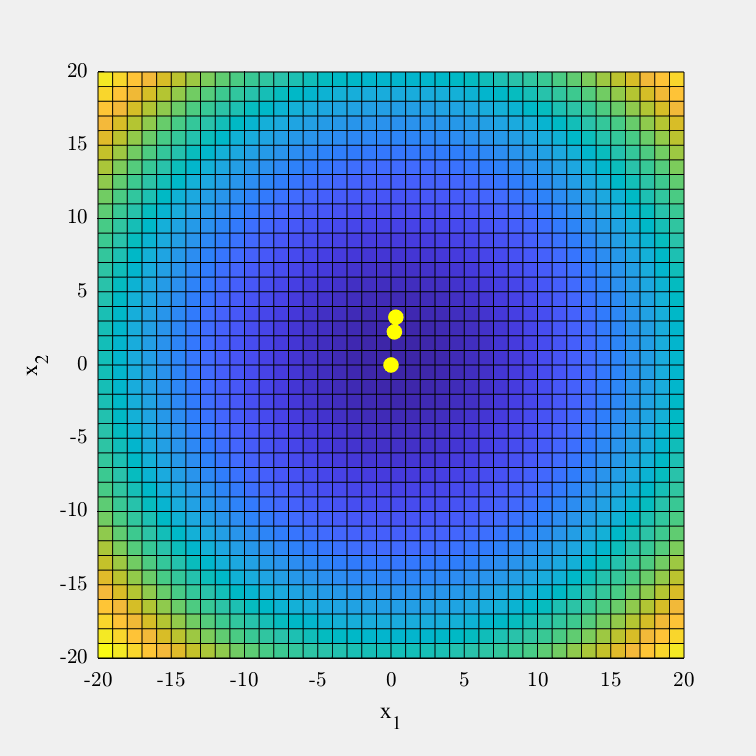


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x = fminunc(@fun,x0, options);

W tym miejscu kończy się część wykonywalna skryptu. Poniżej są definicje użytych funkcji.

#### Definicja funkcji celu

function y = fun(x)
y=x(1).^2+x(2).^2;
end

#### Definicja funkcji rysującej

Jest to bardzo prosty i nieefektywny przykład. Programista powinien unikać niepotrzebnego powtarzania tych samych operacji. 

function stop = trajektorie(x, optimValues, state)
% Na początku narysujemy płaszczyznę wyznaczaną przez funkcję celu.
[X, Y]=meshgrid(-20:1:20, -20:1:20);
figure(1);
surf(X,Y,X.^2+Y.^2);
axis normal;
hold on;

% Nanosimy rozwiązanie obliczone w bieżącej iteracji
plot3(x(1),x(2),fun(x)+10,'.','Color','yellow','MarkerSize',20);

%Ustalamy zakres na osiach
axis([-10 10 -10 10 0 1000]);
axis equal;

%Wykres musi być opisany
xlabel('x_1');
ylabel('x_2');

%Obóćmy płaszczyznę i zablokujmy współczynnik proporcji osi
view(0,90)
axis equal;

% Funkcja kreśląca wykres nie powinna robić nic innego niż kreślić wykresy. Tutaj dodatko
% wypisuje pewne informacje, ale nalezałoby takie rzeczy robić w funkcji
% wyjsciowej:
% https://www.mathworks.com/help/optim/ug/output-functions.html.
% Ja wypiszę informację tylko gdy optymalizator jest w trakcie pracy (są
% jeszcze stany inicjalizacji oraz finalizacji).
if(strcmp(state,'iter'))
    fprintf('Rozwiązanie w i=%g iteracji wynosi x=[%g %g]\n',optimValues.iteration,x(1),x(2))
end


%Składania zobowiązuje nas do zwrócenia zmiennej stop o jakiejś wartości
stop=false;
end

Opracował: dr inż. Grzegorz Bogdan, grzegorz.bogdan@pw.edu.pl, Warszawa, marzec 2023 r.